% készítette: Barányi István
clear all;
close all;
F=[1 -2 0; -2 3 0; -2 -3 0];
r=[1 2 0; 1 1 0; 1 0 0];
sizexy=size(F);

Fe=sum(F)

Fe =     -3    -2     0



for i=1:sizexy(1)
    M(i,:)=cross(r(i,:),F(i,:));
end
Me=sum(M)

Me =      0     0    -2


metsz_x=Me(3)/Fe(2)

metsz_x = 1

metsz_y=Me(3)/Fe(1)*(-1)

metsz_y = -0.6667

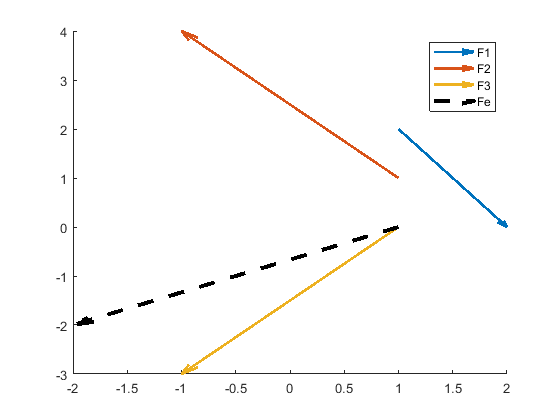


hold on
for i=1:sizexy(1)
    nev="F"+i;
    quiver (r(i,1),r(i,2),F(i,1),F(i,2),0,'LineWidth',2,'DisplayName',nev)
    
end
legend
quiver(metsz_x,0,Fe(1),Fe(2),0,'LineWidth',3,'LineStyle','--','Color','black','DisplayName','Fe')